# Assigning Plots to Variables

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

avgEventsPerDecade = [  74.2 83.8 99.2 159;
                        29 34 31.2 45];
grps = ["All Events" "US Events"];
ikeLat = [17.2; 17.8; 19.8; 21.8; 23.6; 22.8; 21.2; 21.1; 21.5; 23.1; 24.7; 26.1; 28.3; 33.5; 43.3];
ikeLon = [323; 318.7; 312.7; 306.5; 301; 295.1; 289.7; 284.8; 279.7; 276; 273.6; 270; 266; 265.1; 278.5];
labs = ["1800s" "First half of 1900s" "Second half of 1900s" "2000s"];
numEvents = [89; 82; 84; 61; 71; 110; 93; 104; 95; 94; 93; 110; 152; 19];

## Task 1

You can create a handle to a graphics object by assigning the output from a visualization function to a variable. The output of `plot` is a handle to the line object.

`plotHandle` `=` `plot``(``y``)`

The variable `numEvents` contains the number of tropical weather events in the Atlantic ocean (tropical depressions, storms, and hurricanes) in each decade form 1850 to 2010.

p = plot(numEvents, "o")

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: 'none'
          LineWidth: 0.5000
             Marker: 'o'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14]
              YData: [89 82 84 61 71 110 93 104 95 94 93 110 152 19]

  Show all properties


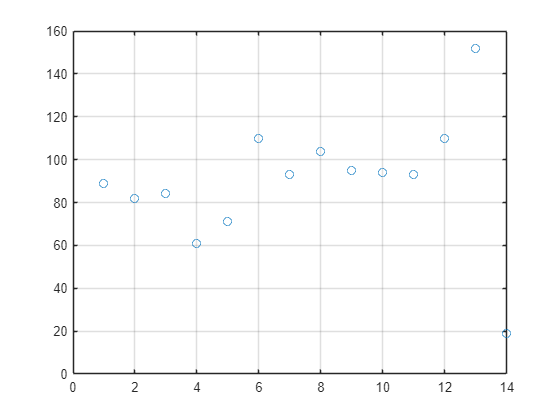

grid on

## Task 2

If you left the semicolon off, you can see the properties of the line plot, `p`. In the `plot` function, you set the markers to be open circles. This is stored in the `Marker` property.

The `geoscatter` function creates a scatter plot of geographic data on top of a map. Scatter plots have different properties than a line plot.

`gs` `=` `geoscatter``(``lat``,``lon``)`

The latitude and longitude data for Hurricane Ike are stored in `ikeLat` and `ikeLon`.

g = geoscatter(ikeLat, ikeLon)

g =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
          LineWidth: 0.5000
       LatitudeData: [17.2000 17.8000 19.8000 21.8000 23.6000 22.8000 21.2000 21.1000 21.5000 23.1000 24.7000 26.1000 28.3000 33.5000 43.3000]
      LongitudeData: [323 318.7000 312.7000 306.5000 301 295.1000 289.7000 284.8000 279.7000 276 273.6000 270 266 265.1000 278.5000]
              ZData: [1×0 double]
           SizeData: 36
              CData: [0 0.4470 0.7410]

  Show all properties


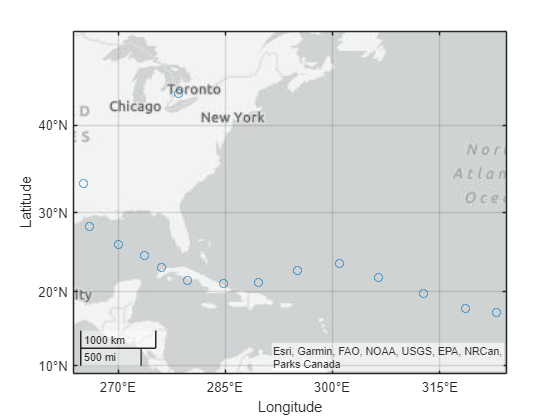

grid on

## Task 3

The properties for `gs` are different from `p`, because they are a different plot types (scatter plot and line plot respectively).

In the workspace you also have data about the average number of storms in a decade for each half century.

b = bar(avgEventsPerDecade)

b =   1×4 Bar array:

    Bar    Bar    Bar    Bar


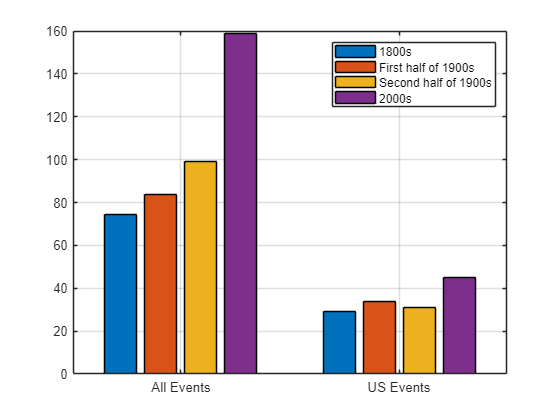

legend(labs)
xticklabels(grps)
grid on

## Task 4

The handles `p`, `g`, and `b` reference charting objects, which are drawn on axes. You can get the current axes with `gca`.

`myAx` `=` `gca`

When you make multiple plots, the current axes keep changing. So, `gca` refers to the axes that are current when it is called.

So if you put `gca` in the code section for Task 4 and run the script, you will get the axes for the bar chart.

ax = gca

ax =   Axes with properties:

             XLim: [0.5091 2.4909]
             YLim: [0 160]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties
